# mtRK2 Test

In this notebook, we're testing an implementation of tensor randomized Kaczmarz with masking and allowing multiple corruptions.

Note: script requires the file mtRK2.m (masking for multiple corruptions) 

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

l = 5;
p = 7;
n = 10;
m = 12;
num_corrupt = 40; % number of corruptions 
size_corrupt= 100; % size of corruptions 
%rng(5)
%generate tensors
A = randn(m,l,n);

X_true = randn(l,p,n);

X_begin = randn(l,p,n)

X_begin = X_begin(:,:,1) =

   -0.8101   -0.3664    0.2803   -0.4419   -1.5672   -0.2799    0.8777
    0.6039   -0.8552    0.5268   -0.9026   -0.5545   -0.7142   -1.1411
    0.1752    0.8002   -0.4706   -0.3292   -1.5430   -0.2104   -1.6009
   -1.3507   -0.7644   -0.8121    0.8685    0.3830   -0.4982   -0.6238
    0.1947   -0.8068   -0.1238   -1.8855   -0.7793    1.0782    0.5246


X_begin(:,:,2) =

    0.0847   -0.1794    0.5158   -0.1981   -1.0456    0.2908   -0.2347
    1.1043    1.3732    1.3535    0.2895   -0.3052   -1.3060    0.2586
   -0.7574    0.0121    1.1038    0.6648    1.5195    0.1272   -0.9580
   -1.2307    0.1966    1.2372   -2.0076   -1.3651    0.1406    0.3497
    0.4884   -2.0099   -1.3731    1.5209    0.5214    0.7053   -0.8238


X_begin(:,:,3) =

    1.1258   -0.1135    0.1624   -0.8393    0.2929   -0.0494   -0.8308
    1.6439   -1.6023    1.9767   -1.4118    0.1432   -1.1935   -0.1952
   -0.6721   -0.2122    0.0090   -0.0522    0.4456    0.4954   -0.6998
   -1.534

%generate consistent measurements
B = tprod(A,X_true);

Now, let's test the implementation of tRK.

%run some iterations of qRK
num_its = 1000; %1000

%Try adding noise!
dims = prod(size(B));
ix_lin = randsample(dims,num_corrupt);

[ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
for i=1:num_corrupt
    % original line - corrupt 1 entry 
    B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt; %original
    %B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = 0;
end 

%[~,its] = qRK(A,B,randn(l,p,n),num_its); %quantile RK
%[~,its] = tRK(A,B,randn(l,p,n),num_its);
%[~,its] = tRK(A,B,X_begin,num_its); % most work done here
%[~,its] = mtRK(A,B,X_begin,num_its,ix_sub2);  % passing in the index of corrupted lateral slice

% save Xnc
%Xnc = its(1,1001) % first iteration of non-corrupted X
%Xc = its(1,1001) % first iteration of corrupted X

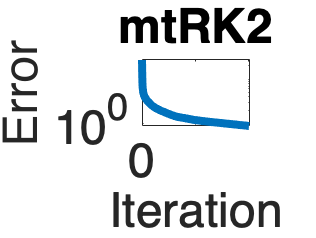


%run some iterations of tRK
num_its = 10000;
%[~,its] = tRK(A,B,randn(l,p,n),num_its); %regular tRK
%[~,its] = mtRK(A,B,randn(l,p,n),num_its, ix_sub1, ix_sub2);
[~,its] = mtRK2(A,B,randn(l,p,n),num_its, ix_sub1, ix_sub2);
%record errors
errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs = [errs,norm(est(:))];
end

%plot errors vs iterations
semilogy(errs,'Linewidth',4)
%set(h(1),'linewidth',2);

title('mtRK2')
xlabel ('Iteration')
ylabel('Error')
fontsize(24,"points")